# Plots of isotropy, dispersion and kurtosis

clear all
close all


% Observations
obs_traj = load ('../data/traj_09_03_13_clean.mat');

% delete sections in the Scotia Sea.
obs_traj.Yc(obs_traj.Xc>-82) = NaN;
obs_traj.Xc(obs_traj.Xc>-82) = NaN;

% use forward differencing to estimate the velocity 
Unew = nan*obs_traj.Xc;
Vnew = nan*obs_traj.Xc;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(obs_traj.Xc)*cor.*cosd(obs_traj.Yc(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(obs_traj.Yc)*cor/dt; 

obs_traj.Uc = Unew; 
obs_traj.Vc = Vnew; 

% Models
d=[4, 10];

for i =1:length(d)
    [mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));
    
    % get the velocity from forward differencing (will be important for structure functions)
    Unew = nan*mod_traj(i).X;
    Vnew = nan*mod_traj(i).X;
    dt = 1*24*3600; 
    cor = 110*1e3; 
    
    Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
    Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 
    
    mod_traj(i).U = Unew; 
    mod_traj(i).V = Vnew; 
    
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-70) = NaN;
    
end

depth = -747.2217

depth = -1.4749e+03

% separation time series from observatios
sep_obs = calculate_seperation_timeseries(obs_traj);

%% Settings
plevel = [500 1000 1800]; % how large are the bins
ndays  = 100; % how long to track a pair
pdiff  = 200; % what is the p difference that we allow.

% Distance pairs
distance_class(1).dist = [10,15]*1e3;
distance_class(2).dist = [30,35]*1e3;

%% get the right pairs
for i =1:length(distance_class)
    for j=1:length(plevel)-1
        [obs_pairs(j,i), obs_sep(j,i)] = find_pairs(sep_obs, distance_class(i).dist, [plevel(j) plevel(j+1)], pdiff, ndays);
    end
end

%% calc sep models
for i = 1:length(distance_class)
    for j =1:length(d)
        mod_sep(j,i) = model_sep_calcs(mod_traj(j), distance_class(i).dist); 
    end
end

% dispersion
% model 
for i =1:length(distance_class)
    for j =1:length(d)       
            
            Mod_disp(j,i) = rel_disp(mod_sep(j,i).sep, ndays);
            
    end
end

% obs
for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n = 1:500
            y = randsample(obs_pairs(j,i),obs_pairs(j,i),true);
            Obsbs(n,j,i) = rel_disp(obs_sep(j,i).sep(y), ndays);
        end
    end
end

%% Convert from structures to arrays for simpler calcs.

for i =1:length(distance_class)
    for j =1:length(d)
        Moddisp(:,j,i) = Mod_disp(j,i).avdisp/1e6; 
        Moddisp_zon(:,j,i) = Mod_disp(j,i).avdispzon/1e6;
        Moddisp_mer(:,j,i) = Mod_disp(j,i).avdispmer/1e6;
    end
end

for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n=1:500 
            Obsdisp(:,n,j,i) = Obsbs(n,j,i).avdisp/1e6;
            Obsdisp_zon(:,n,j,i) = Obsbs(n,j,i).avdispzon/1e6;
            Obsdisp_mer(:,n,j,i) = Obsbs(n,j,i).avdispmer/1e6;
        end
    end
end

[Obsdisp_mean, Obsdisp_ci] = errbar4shaded(Obsdisp);
[Obsdisp_mean, Obsdisp_cilog] = errbar4shadedlog(Obsdisp);

## Isotropy

%% Isotropy 

for i =1:length(distance_class)
    for j =1:2
        for n=1:500
            Iso_obs_bs(:,n,j,i) = Obsbs(n,j,i).avdispzon.^0.5./Obsbs(n,j,i).avdispmer.^0.5; 
            Robs_bs(:,n,j,i) = Obsbs(n,j,i).avdisp.^0.5; 
        end
    end
end

%%
[Iso_obs, Iso_obsci] = errbar4shaded(Iso_obs_bs); 
Robs = squeeze(nanmean(Robs_bs,2)); 

for i =1:length(distance_class)
    for j =1:2
            Iso_mod(:,j,i) = Mod_disp(j,i).avdispzon.^0.5./Mod_disp(j,i).avdispmer.^0.5;
            Rmod(:,j,i) = Mod_disp(j,i).avdisp.^0.5; 
    end
end

T = 0:99;

colors = get(gca,'ColorOrder');
col_num = [1,4; 2, 5];

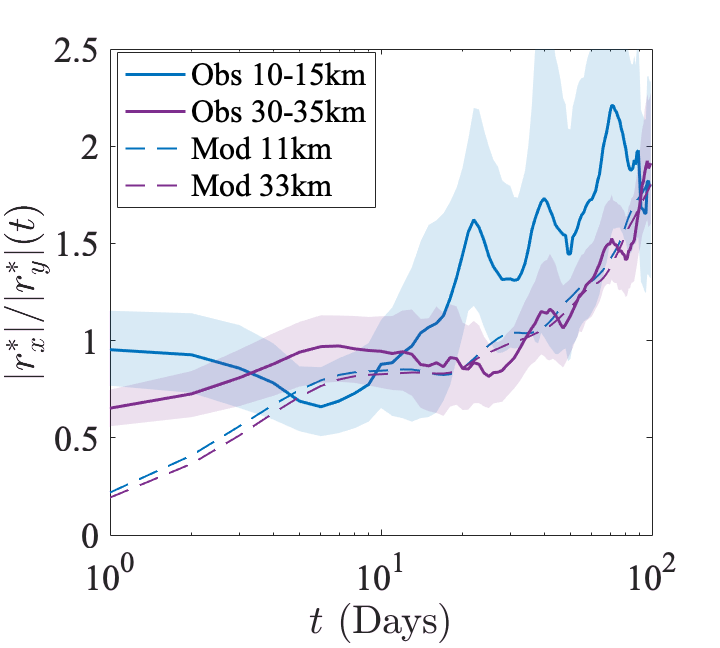


% Iso plots with time 
% Figure at first depth 
clear h g
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')

j=1;

for i =1:length(distance_class)
    
    h(i)= shadedErrorBar_semilogx(T+0.001, Iso_obs(:,j,i), Iso_obsci(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
                hold all
    g(i) = semilogx(T+0.001, Iso_mod(:,j,i), '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.);
    
    
end
legend([h(1).mainLine,h(2).mainLine, g], ...
    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km'},'location','best') 
axis([1 100 0 2.5])

set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$|r_x^*|/|r_y^*| (t)$', 'Interpreter','Latex')
print('iso_t_1.eps','-depsc', '-r400')

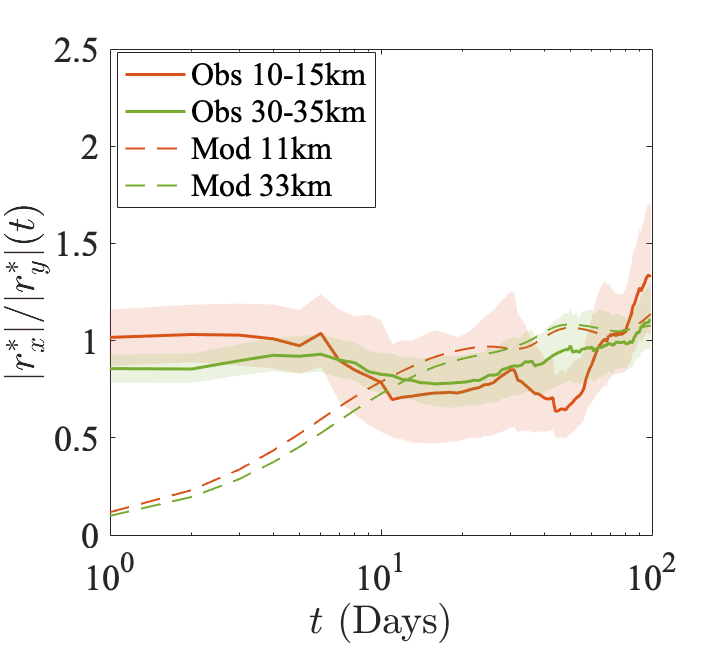

% Iso plots with time 
% Figure at first depth 
clear h g
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')
colors = get(gca,'ColorOrder');
j=2;
for i =1:length(distance_class)
    
    h(i)= shadedErrorBar_semilogx(T+0.001, Iso_obs(:,j,i), Iso_obsci(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
                hold all
    g(i) = semilogx(T+0.001, Iso_mod(:,j,i), '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.);
    
    
end
legend([h(1).mainLine,h(2).mainLine, g], ...
    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km'},'location','best') 
axis([1 100 0 2.5])

set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$|r_x^*|/|r_y^*| (t)$', 'Interpreter','Latex')
print('iso_t_2.eps','-depsc', '-r400')

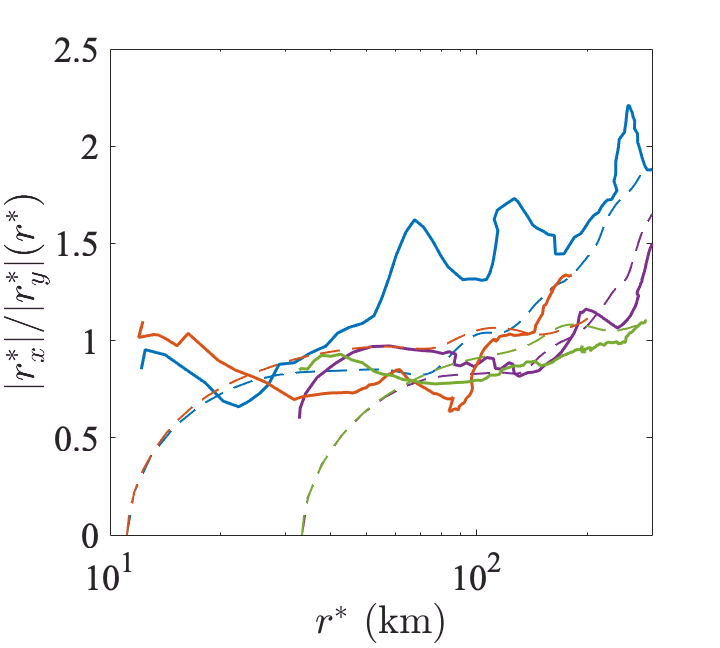

%% Figure at all depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')
for j=1:2
for i =1:length(distance_class)
    
    h(i)= semilogx(Robs(:,j,i)/1e3, Iso_obs(:,j,i), ...
                    '-','linewidth',1.5,'color',colors(col_num(j,i),:));
                hold all
    g(i) = semilogx(Rmod(:,j,i)/1e3, Iso_mod(:,j,i), '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.);

end
end

axis([10 300 0 2.5])

set(gca,'FontSize', 18,'fontname','times')
xlabel('$r^*$ (km)', 'Interpreter','Latex') 
ylabel('$|r_x^*|/|r_y^*| (r^*)$', 'Interpreter','Latex')
print('iso_D.eps','-depsc', '-r400')

## Dispersion

log-log

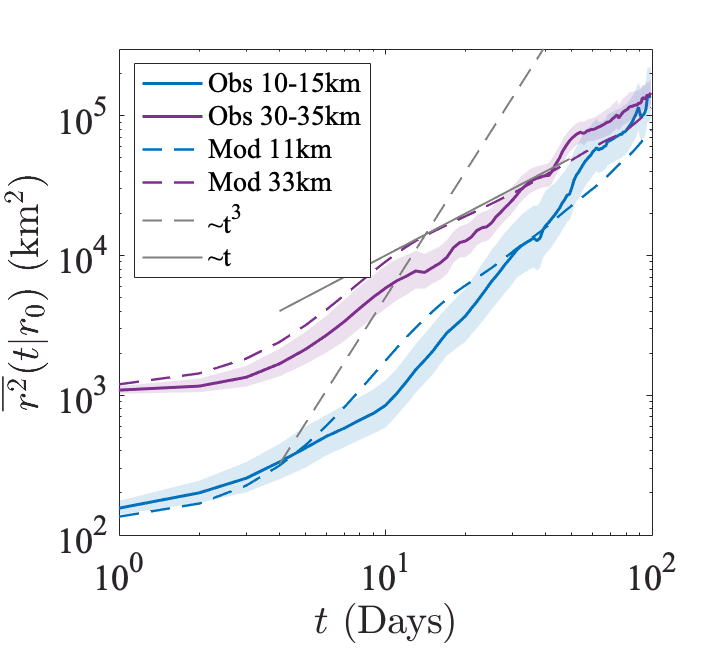

% Figure at first depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=1;
for i =1:length(distance_class)
    
    h(i)= shadedErrorBar_log(T+0.001, Obsdisp_mean(:,j,i), Obsdisp_cilog(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
                hold all
    g(i) = loglog(T+0.001, Moddisp(:,j,i), '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

Tax= T(5:50);
t3 = loglog(Tax, 10^0.7*Tax.^3,'--', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
%t2 = loglog(Tax, 10^8.15*Tax.^2,'-.', 'color', [0.5 0.5 0.5]);
t1 = loglog(Tax, 10^3.*Tax, 'color', [0.5 0.5 0.5], 'linewidth', 1.);


A = legend([h(1).mainLine,h(2).mainLine,  g, t3, t1], ...
    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km','~t^3','~t'},'location','best','fontsize',14); 
axis([1 100 10^2 3*10^5])
%legend boxoff
set(A, 'location','best')
set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t |r_0)$ (km$^2$)', 'Interpreter','Latex')
print('rel_disp_shallow.eps', '-depsc','-r400')

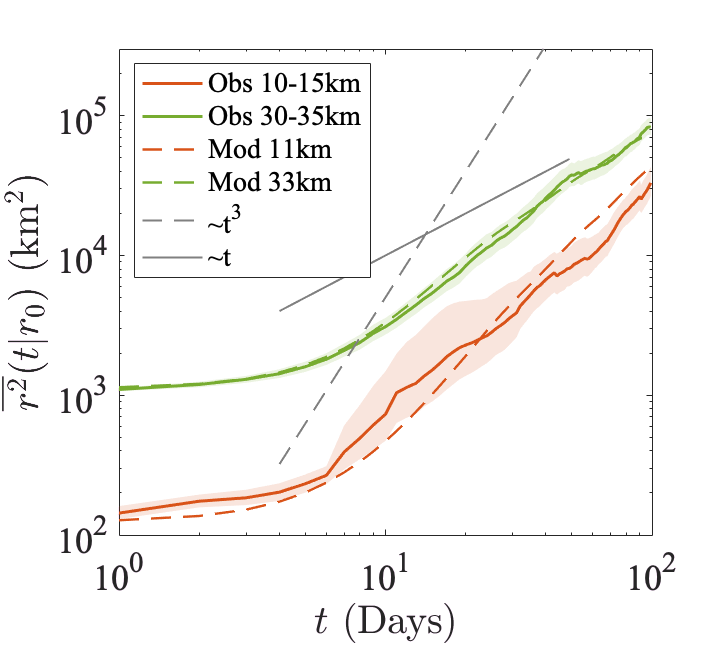

% Figure at second depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=2;
for i =1:length(distance_class)
    
    h(i)= shadedErrorBar_log(T+0.001, Obsdisp_mean(:,j,i), Obsdisp_cilog(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
                hold all
    g(i) = loglog(T+0.001, Moddisp(:,j,i), '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

Tax= T(5:50);
t3 = loglog(Tax, 10^0.7*Tax.^3,'--', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
%t2 = loglog(Tax, 10^8.15*Tax.^2,'-.', 'color', [0.5 0.5 0.5]);
t1 = loglog(Tax, 10^3.*Tax, 'color', [0.5 0.5 0.5], 'linewidth', 1.);


A = legend([h(1).mainLine,h(2).mainLine,  g, t3, t1], ...
    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km','~t^3','~t'},'location','best','fontsize',14); 
axis([1 100 10^2 3*10^5])
%legend boxoff
set(A, 'location','best')
set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t| r_0)$ (km$^2$)', 'Interpreter','Latex')
print('rel_disp_deep.eps', '-depsc','-r400')

semi-log

%% Convert from structures to arrays for simpler calcs.

for i =1:length(distance_class)
    for j =1:length(d)
        Moddisp_normini(:,j,i) = Mod_disp(j,i).avdisp/Mod_disp(j,i).avdisp(1); 
    end
end

for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n=1:500 
            Obsdisp_normini(:,n,j,i) = Obsbs(n,j,i).avdisp/Obsbs(n,j,i).avdisp(1);
            
        end
    end
end

%[Obsdisp_mean, Obsdisp_ci] = errbar4shaded(Obsdisp);
[Obsdisp_normini_mean, Obsdisp_normini_cilog] = errbar4shadedlog(Obsdisp_normini);

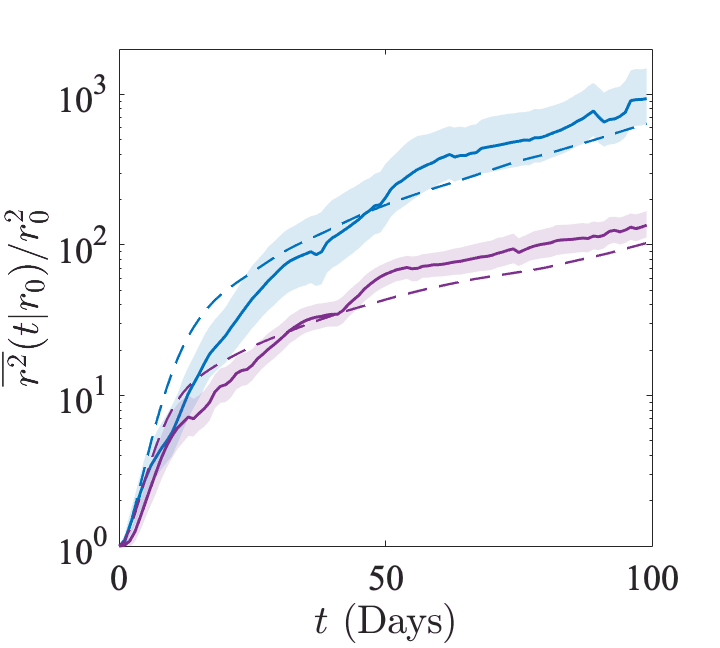

% Figure at first depth 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=1;
for i =1:length(distance_class)
    
   m(i)  = shadedErrorBar_semilogy(T+0.001, Obsdisp_normini_mean(:,j,i), Obsdisp_normini_cilog(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
hold all 
   %  h(i)= semilogy(T, Obsdisp_mean(:,1,k), ...
   %                'o-','linewidth',3,'color',colors(i*2,:));
   
                hold all
    g(i) = semilogy(T, Moddisp_normini(:,j,i), '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end
%A = legend([h(1),h(2), h(3), g], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km'}) ;
%A = legend([m(1).mainLine,m(2).mainLine, g], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km'}) ;
axis([0 100 1 2000])
%legend boxoff
%set(A, 'location','best')
set(gca,'FontSize', 18, 'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t| r_0)/r_0^2$', 'Interpreter','Latex')
print('rel_disp_log_shallow.eps', '-depsc','-r400')

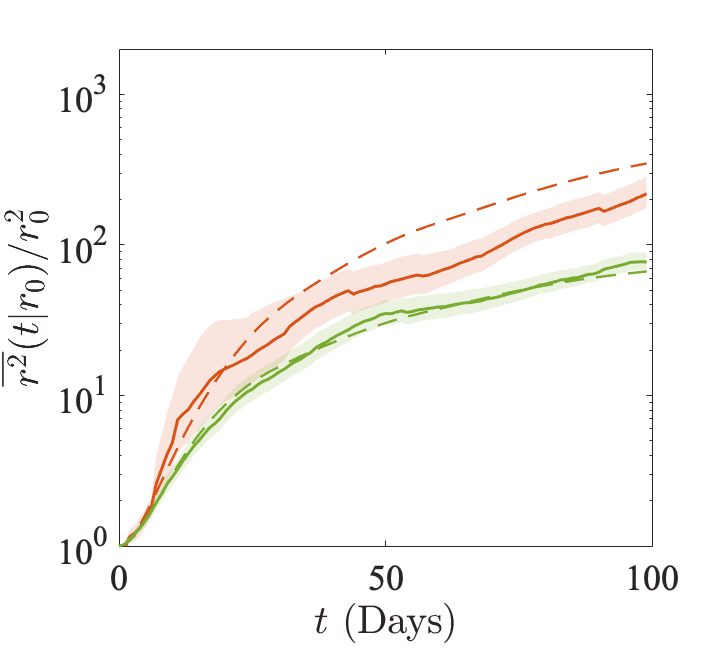

% Figure at first depth 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=2;
for i =1:length(distance_class)
    
   m(i)  = shadedErrorBar_semilogy(T+0.001, Obsdisp_normini_mean(:,j,i), Obsdisp_normini_cilog(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
hold all 
   %  h(i)= semilogy(T, Obsdisp_mean(:,1,k), ...
   %                'o-','linewidth',3,'color',colors(i*2,:));
   
                hold all
    g(i) = semilogy(T, Moddisp_normini(:,j,i), '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end
%A = legend([h(1),h(2), h(3), g], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km'}) ;
%A = legend([m(1).mainLine,m(2).mainLine, g], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km'}) ;
axis([0 100 1 2000])
%legend boxoff
%set(A, 'location','best')
set(gca,'FontSize', 18, 'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t| r_0)/r_0^2$', 'Interpreter','Latex')
print('rel_disp_log_deep.eps', '-depsc','-r400')

D23 norm

%% Convert from structures to arrays for simpler calcs.

for i =1:length(distance_class)
    for j =1:length(d)
        Moddisp_normrich(:,j,i) = (Mod_disp(j,i).avdisp/1e6).^(1/3)  - (Mod_disp(j,i).avdisp(1)/1e6).^(1/3); 
    end
end

for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n=1:500 
            Obsdisp_normrich(:,n,j,i) = (Obsbs(n,j,i).avdisp/1e6).^(1/3) - (Obsbs(n,j,i).avdisp(1)/1e6).^(1/3);
            
        end
    end
end

%[Obsdisp_mean, Obsdisp_ci] = errbar4shaded(Obsdisp);
[Obsdisp_normrich_mean, Obsdisp_normrich_cilog] = errbar4shadedlog(Obsdisp_normrich);

Obsdisp_normrich_mean(Obsdisp_normrich_mean<0) = NaN;
Obsdisp_normrich_cilog(Obsdisp_normrich_cilog<0) = NaN;

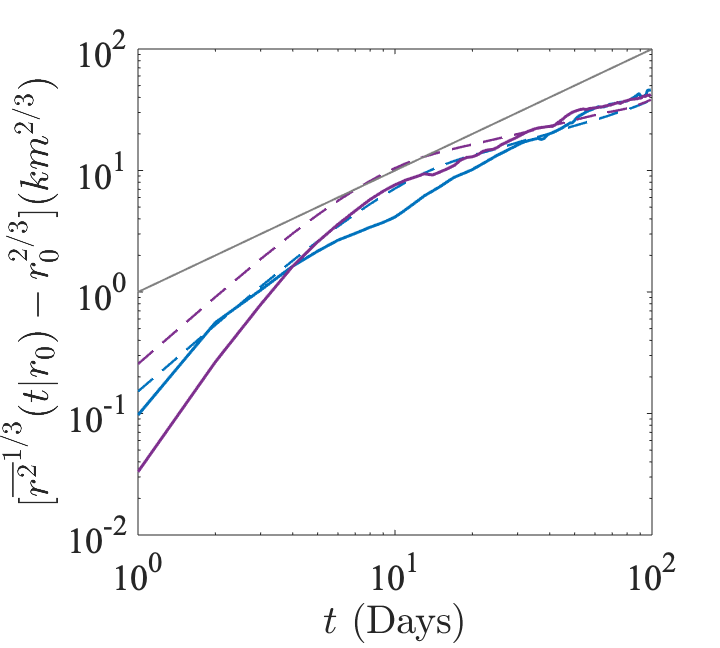

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=1;
colors = get(gca,'ColorOrder');
for i =1:length(distance_class)
    
    h(i)= loglog(T+0.001, Obsdisp_normrich_mean(:,j,i), ...
                    'linewidth',1.5,'color',colors(col_num(j,i),:));
                hold all
    g(i) = loglog(T, Moddisp_normrich(:,j,i), '--', ...
        'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

t1= loglog(T, T,'-','color',[0.5 0.5 0.5], 'linewidth',1);
axis([1 100 1e-2 100])
%A = legend([h(1),h(2), h(3), g, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km', '~t^1'}) 
%axis([1 100 10^6.9 10^11])
%legend boxoff
%set(A, 'location','southeast')
set(gca,'FontSize', 18,'fontname', 'times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('[$\overline{r^{2}}^{1/3}(t | r_0) - r_0^{2/3}] (km^{2/3})$', 'Interpreter','Latex')
print('rel_disp_rich_shallow.eps', '-depsc','-r400')

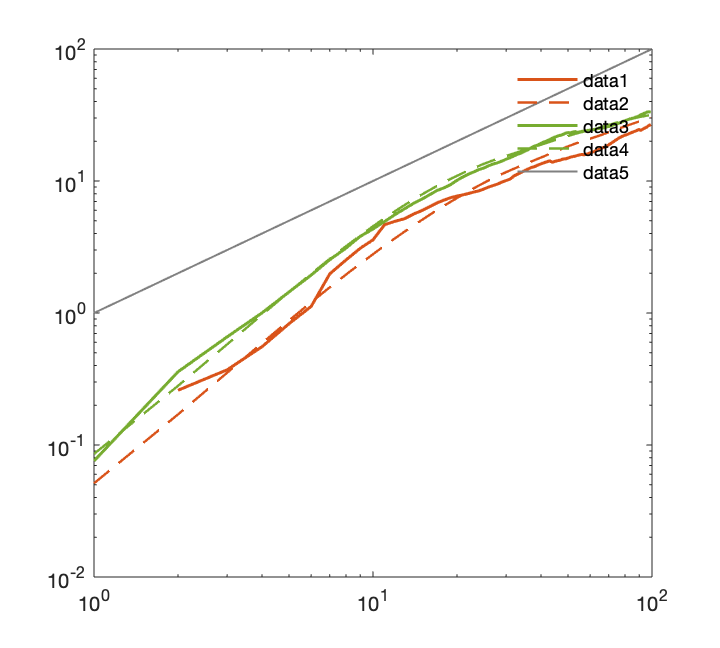

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=2;
for i =1:length(distance_class)
    
    h(i)= loglog(T+0.001, Obsdisp_normrich_mean(:,j,i), ...
                    'linewidth',1.5,'color',colors(col_num(j,i),:));
                hold all
    g(i) = loglog(T, Moddisp_normrich(:,j,i), '--', ...
        'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

t1= loglog(T, T,'-','color',[0.5 0.5 0.5], 'linewidth',1);
axis([1 100 1e-2 100])
%A = legend([h(1),h(2), h(3), g, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km', '~t^1'}) 
%axis([1 100 10^6.9 10^11])
legend boxoff

set(A, 'location','southeast')

Unrecognized function or variable 'A'.

set(gca,'FontSize', 18,'fontname', 'times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('[$\overline{r^{2}}^{1/3}(t | r_0) - r_0^{2/3}] (km^{2/3})$', 'Interpreter','Latex')
print('rel_disp_rich_deep.eps', '-depsc','-r400')

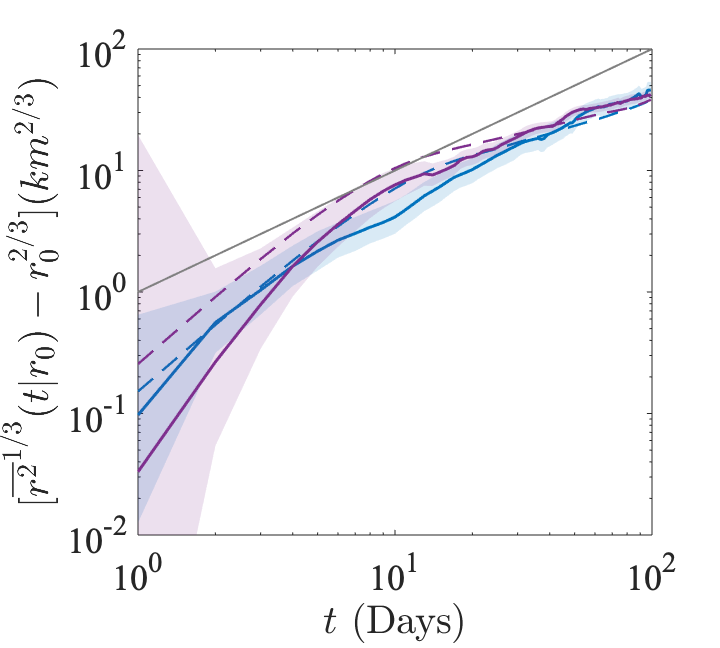

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=1;
colors = get(gca,'ColorOrder');
for i =1:length(distance_class)
    
    %h(i)= loglog(T+0.001, Obsdisp_normrich_mean(:,j,i), ...
    %                'linewidth',1.5,'color',colors(col_num(j,i),:));
    h(i) = shadedErrorBar_log(T+0.001, Obsdisp_normrich_mean(:,j,i), Obsdisp_normrich_cilog(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
                hold all
    g(i) = loglog(T, Moddisp_normrich(:,j,i), '--', ...
        'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

t1= loglog(T, T,'-','color',[0.5 0.5 0.5], 'linewidth',1);
axis([1 100 1e-2 100])
%A = legend([h(1),h(2), h(3), g, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km', '~t^1'}) 
%axis([1 100 10^6.9 10^11])
%legend boxoff
%set(A, 'location','southeast')
set(gca,'FontSize', 18,'fontname', 'times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('[$\overline{r^{2}}^{1/3}(t | r_0) - r_0^{2/3}] (km^{2/3})$', 'Interpreter','Latex')
print('rel_disp_rich_shallow.eps', '-depsc','-r400')

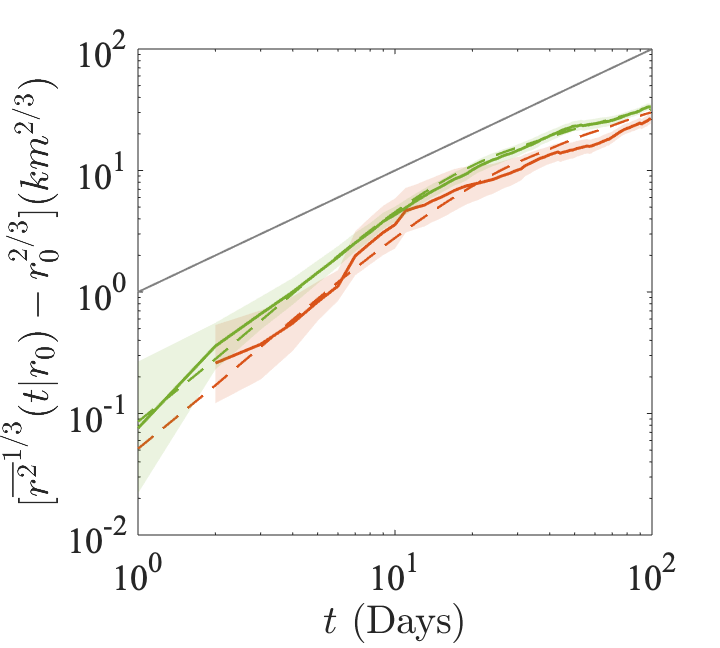

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=2;
colors = get(gca,'ColorOrder');
for i =1:length(distance_class)
    
    %h(i)= loglog(T+0.001, Obsdisp_normrich_mean(:,j,i), ...
    %                'linewidth',1.5,'color',colors(col_num(j,i),:));
    h(i) = shadedErrorBar_log(T+0.001, Obsdisp_normrich_mean(:,j,i), Obsdisp_normrich_cilog(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
                hold all
    g(i) = loglog(T, Moddisp_normrich(:,j,i), '--', ...
        'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

t1= loglog(T, T,'-','color',[0.5 0.5 0.5], 'linewidth',1);
axis([1 100 1e-2 100])
%A = legend([h(1),h(2), h(3), g, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km', '~t^1'}) 
%axis([1 100 10^6.9 10^11])
%legend boxoff
%set(A, 'location','southeast')
set(gca,'FontSize', 18,'fontname', 'times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('[$\overline{r^{2}}^{1/3}(t | r_0) - r_0^{2/3}] (km^{2/3})$', 'Interpreter','Latex')
print('rel_disp_rich_deep.eps', '-depsc','-r400')

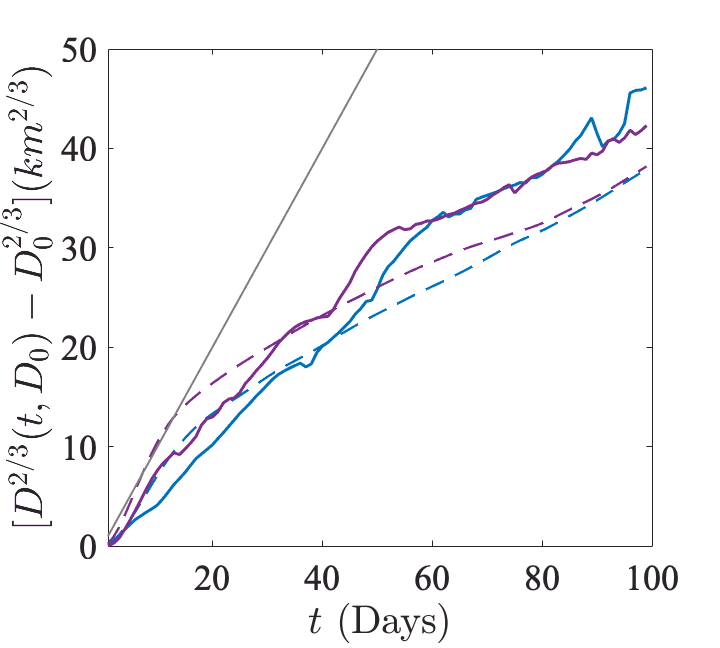

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=1;
for i =1:length(distance_class)
    
    h(i)= plot(T+0.001, Obsdisp_normrich_mean(:,j,i), ...
                    'linewidth',1.5,'color',colors(col_num(j,i),:));
                hold all
    g(i) = plot(T, Moddisp_normrich(:,j,i), '--', ...
        'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

t1= loglog(T, T,'-','color',[0.5 0.5 0.5], 'linewidth',1);
axis([1 100 0 50])
%A = legend([h(1),h(2), h(3), g, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km', '~t^1'}) 
%axis([1 100 10^6.9 10^11])
legend boxoff
%set(A, 'location','southeast')
set(gca,'FontSize', 18,'fontname', 'times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('[$D^{2/3}(t, D_0) - D_0^{2/3}] (km^{2/3})$', 'Interpreter','Latex')

%print('rel_disp_rich_shallow.eps', '-depsc','-r400')

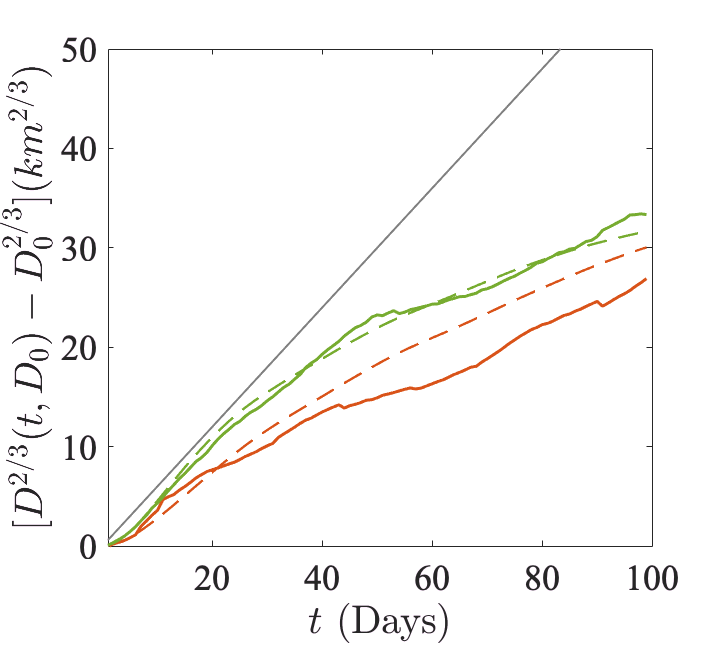

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=2;
for i =1:length(distance_class)
    
    h(i)= plot(T+0.001, Obsdisp_normrich_mean(:,j,i), ...
                    'linewidth',1.5,'color',colors(col_num(j,i),:));
                hold all
    g(i) = plot(T, Moddisp_normrich(:,j,i), '--', ...
        'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

t1= loglog(T, 0.6*T,'-','color',[0.5 0.5 0.5], 'linewidth',1);
axis([1 100 0 50])
%A = legend([h(1),h(2), h(3), g, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km', '~t^1'}) 
%axis([1 100 10^6.9 10^11])
legend boxoff
%set(A, 'location','southeast')
set(gca,'FontSize', 18,'fontname', 'times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('[$D^{2/3}(t, D_0) - D_0^{2/3}] (km^{2/3})$', 'Interpreter','Latex')

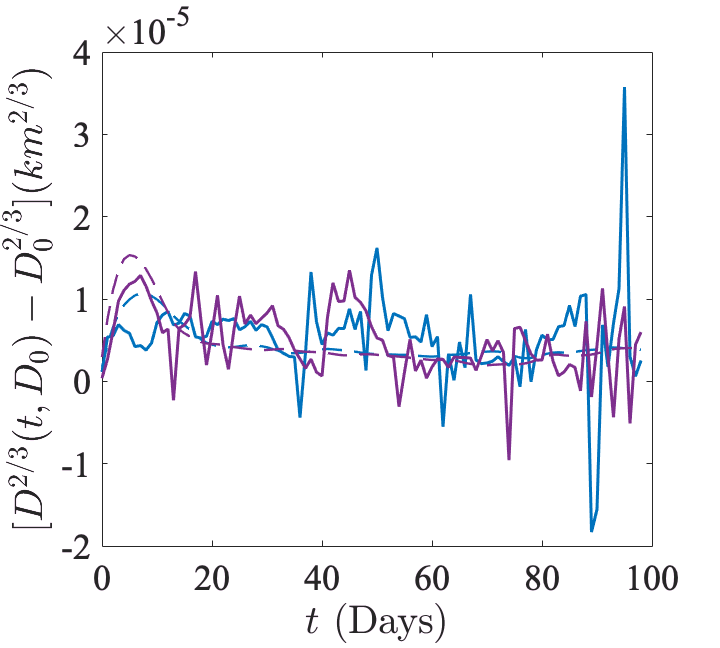

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
j=1;
for i =1:length(distance_class)
    
    h(i)= plot(T(1:99), diff(Obsdisp_normrich_mean(:,j,i))/24/3600, ...
                    'linewidth',1.5,'color',colors(col_num(j,i),:));
                hold all
    g(i) = plot(T(1:99), diff(Moddisp_normrich(:,j,i))/24/3600, '--', ...
        'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    
end

%t1= loglog(T, 0.6*T,'-','color',[0.5 0.5 0.5], 'linewidth',1);
%axis([1 100 0 50])
%A = legend([h(1),h(2), h(3), g, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km', '~t^1'}) 
%axis([1 100 10^6.9 10^11])
legend boxoff
%set(A, 'location','southeast')
set(gca,'FontSize', 18,'fontname', 'times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('[$D^{2/3}(t, D_0) - D_0^{2/3}] (km^{2/3})$', 'Interpreter','Latex')

## Kurtosis

%% look at kurtosis

clear kurt_mod kurt_obs

for i =1:length(distance_class)
    for j =1:2        
            kurt_mod(:,j,i) = nanmean(Mod_disp(j,i).disp'.^2, 1)./nanmean(Mod_disp(j,i).disp', 1).^2  ;
            %kurt_obs(:,j,i) = nanmean(Obs_disp(j,i).disp'.^2, 1)./nanmean(Obs_disp(j,i).disp', 1).^2  ;
    end
end

%%
for i=1:length(distance_class)
     for j =1:2
         for n=1:500
            kurt_obsbs(:, n, j, i) = nanmean(Obsbs(n,j,i).disp'.^2, 1)./nanmean(Obsbs(n,j,i).disp', 1).^2  ;
            %kurtosis(Obsbs(n,j,i).disp'.^0.5,1); 
         end
     end
end

%%
[kurt_obs_mean, kurt_obs_ci] = errbar4shaded(kurt_obsbs);

[kurt_obs_mean, kurt_obs_cilog] = errbar4shadedlog(kurt_obsbs);

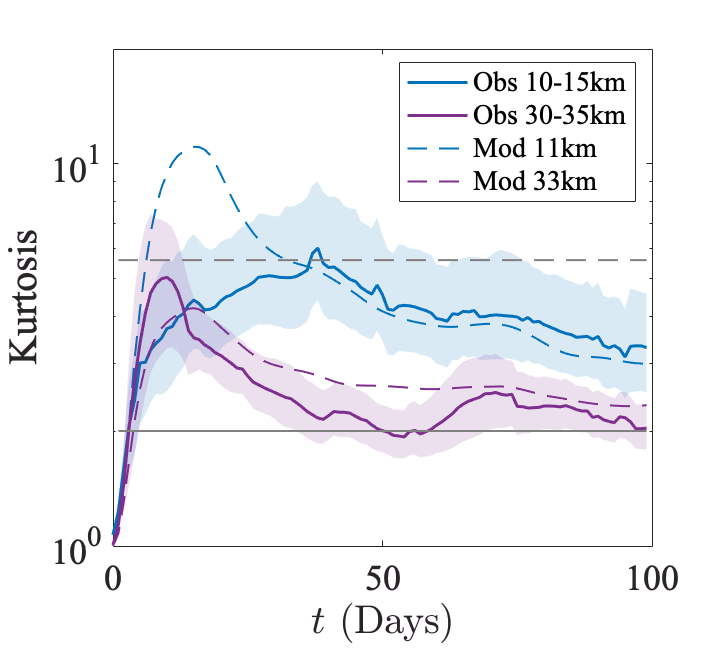


%
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
clear h g
for i=1:length(distance_class) 
    for j=1
        
        h(i) = shadedErrorBar_semilogy(T, kurt_obs_mean(:,j,i), kurt_obs_cilog(:,:,j,i), ...
            {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
        hold all
        g(i) = semilogy(T, kurt_mod(:,j,i),'--', 'color', colors(col_num(j,i),:), 'linewidth',1) ;
        
    end
end

semilogy(T, 5.6*T./T, '--', 'color',[0.5 0.5 0.5], 'linewidth', 1)
semilogy(T, 2*T./T, '-', 'color',[0.5 0.5 0.5], 'linewidth', 1)

%semilogy(T, exp(8*T/fit_parms_obs(j).Tlung), '-', 'color',[0.5 0.5 0.5], 'linewidth', 1) 

%A = legend([h(1).mainLine, h(2).mainLine, h(3).mainLine, g], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km'});
A = legend([h(1).mainLine,h(2).mainLine,  g], ...
    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km'},'location','best','fontsize',14);     

axis([0 100 1 20])

set(gca, 'FontSize', 18,'fontname','times') 
xlabel('$t$ (Days)', 'Interpreter', 'Latex')
ylabel('Kurtosis')
%saveas(gcf,'../figures/kurt_shallow.eps', 'epsc')
print('kurt_shallow.eps', '-depsc','-r400')

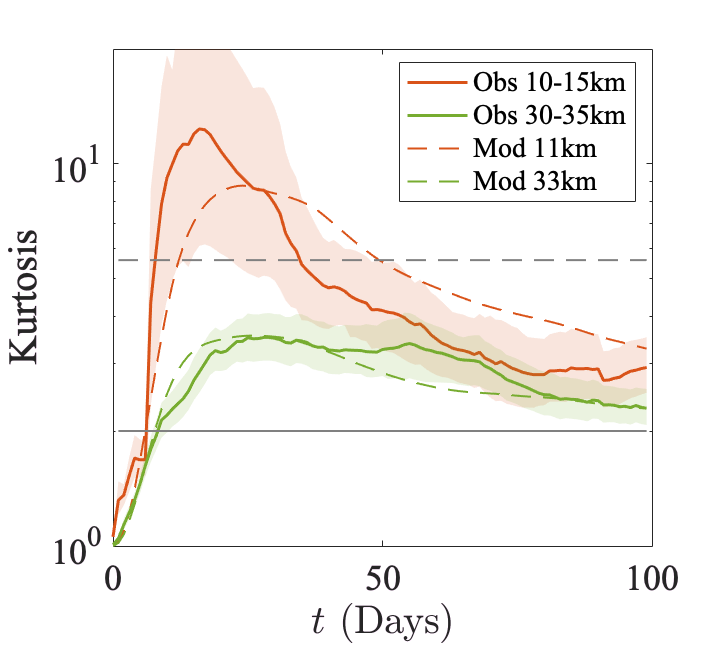

%
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','OpenGL')
clear h g
for i=1:length(distance_class) 
    for j=2
        
        h(i) = shadedErrorBar_semilogy(T, kurt_obs_mean(:,j,i), kurt_obs_cilog(:,:,j,i), ...
            {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
        hold all
        g(i) = semilogy(T, kurt_mod(:,j,i),'--', 'color', colors(col_num(j,i),:), 'linewidth',1) ;
        
    end
end

semilogy(T, 5.6*T./T, '--', 'color',[0.5 0.5 0.5], 'linewidth', 1)
semilogy(T, 2*T./T, '-', 'color',[0.5 0.5 0.5], 'linewidth', 1)

%semilogy(T, exp(8*T/fit_parms_obs(j).Tlung), '-', 'color',[0.5 0.5 0.5], 'linewidth', 1) 

%A = legend([h(1).mainLine, h(2).mainLine, h(3).mainLine, g], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Obs 50-55km','Mod 11km', 'Mod 33km', 'Mod 50km'});
A = legend([h(1).mainLine,h(2).mainLine,  g], ...
    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km'},'location','best','fontsize',14);     

axis([0 100 1 20])

set(gca, 'FontSize', 18,'fontname','times') 
xlabel('$t$ (Days)', 'Interpreter', 'Latex')
ylabel('Kurtosis')
%saveas(gcf,'../figures/kurt_shallow.eps', 'epsc')
print('kurt_deep.eps', '-depsc','-r400')